# Operaciones arreglo (elemento a elemento)

MATLAB tiene dos tipos diferentes de operaciones aritméticas: operaciones arreglo y operaciones matriciales. Es posible utilizar estas operaciones aritméticas para realizar cálculos numéricos, por ejemplo, sumar dos números, elevar los elementos de una matriz a una potencia determinada o multiplicar dos matrices.

Las operaciones arreglo realizan las operaciones entre los correspondientes elementos de las matrices involucradas. No obstante, se debe destacar lo siguiente:

- Si las matrices tienen el mismo tamaño, entonces cada elemento de la primer matriz se empareja con el elemento en la misma ubicación de la segunda matriz.

- Si las matrices tienen tamaños compatibles, entonces cada entrada se expande implícitamente según sea necesario para que coincida con el tamaño de la otra.

- Si las matrices no son del mismo tamaño ni tienen tamaños compatibles, entonces no se realiza la operación y MATLAB devuelve error.

Estas son algunas combinaciones de escalares, vectores y matrices que tienen tamaños compatibles:

**Figura 1.** Dos entradas que son exactamente del mismo tamaño.

**Figura 2.** Una entrada es un escalar.

**Figura 3.** Una entrada es una matriz y la otra es un vector columna con el mismo número de filas.

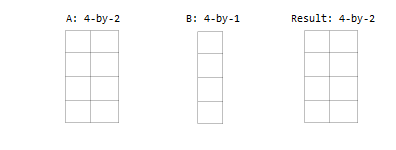

**Figura 4.** Una entrada es un vector columna y la otra es un vector fila.

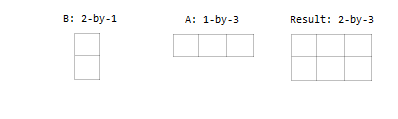

*Todas las figuras fueron tomadas de *[*MathWorks: Compatible Array Sizes for Basic Operations*](https://www.mathworks.com/help/matlab/matlab_prog/compatible-array-sizes-for-basic-operations.html)

Para obtener más información puede consultar el material adjunto en Material adicional.

## Operaciones elementales

Previamente se estudió las operaciones con escalares. Ahora se expandirá lo explicado anteriormente a operaciones elementales con matrices.

**Figura 5.** Todas las operaciones arreglo dentro de MATLAB.

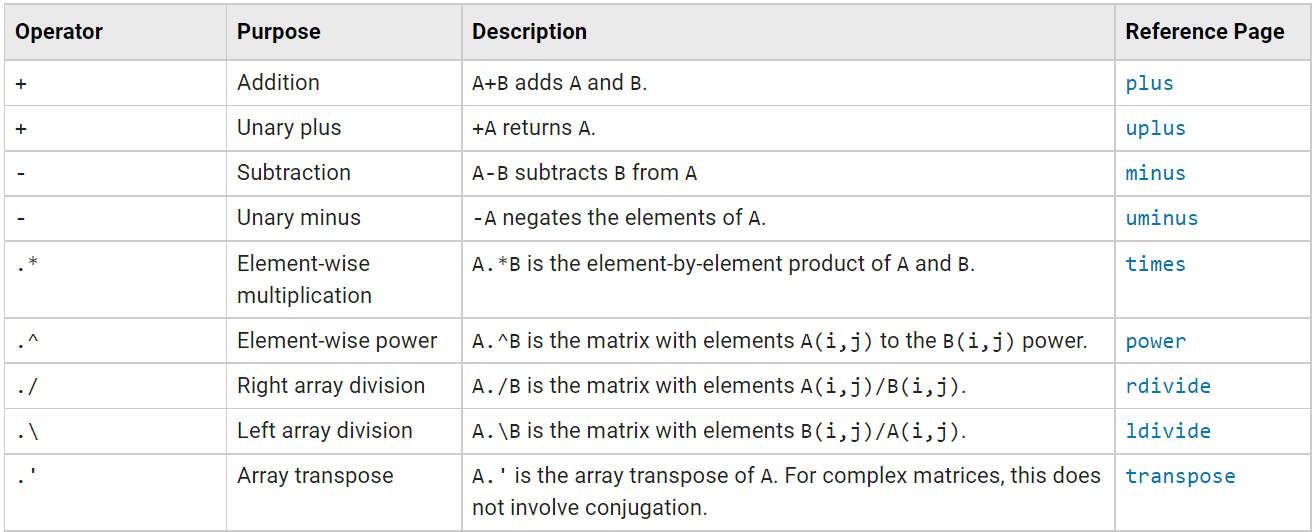

*Tomado de *[*MathWorks: Array vs. Matrix Operations*](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)*.*

Para el estudio de cada operación elemental se utilizarán los siguientes vectores y matrices.

clear

% Creación de vectores.
a = [1 2 3];
b = [3 2 1]';

% Creación de matrices.
A = [1 2 3
     4 5 6
     7 8 9];
B = [9 8 7
     6 5 4
     3 2 1];

Para todas las operaciones se debe tener en cuenta el tamaño de las matrices involucradas, así como también la expansión que se realizará siempre que sea posible. Esto se encuentra detallado en las figuras 1, 2, 3 y 4.

### Suma y resta

#### Ejemplo 1

% Visualización del vector.
a

a =      1     2     3


% Operación.
a + 1

ans =      2     3     4


#### Ejemplo 2

% Visualización de la matriz.
A

A =      1     2     3
     4     5     6
     7     8     9


% Visualización de la matriz.
B

B =      9     8     7
     6     5     4
     3     2     1


% Operación.
A - B

ans =     -8    -6    -4
    -2     0     2
     4     6     8


#### Ejemplo 3

% Visualización del vector.
a

a =      1     2     3


% Visualización del vector.
b

b =      3
     2
     1


% Operación.
a + b

ans =      4     5     6
     3     4     5
     2     3     4


### Multiplicación y potencia

#### Ejemplo 1

% Visualización del vector.
a

a =      1     2     3


% Operación.
a .* 2

ans =      2     4     6


#### Ejemplo 2

% Visualización del vector.
A

A =      1     2     3
     4     5     6
     7     8     9


% Visualización del vector.
B

B =      9     8     7
     6     5     4
     3     2     1


% Operación.
A .* B

ans =      9    16    21
    24    25    24
    21    16     9


#### Ejemplo 3

% Visualización del vector.
a

a =      1     2     3


% Visualización del vector.
b

b =      3
     2
     1


% Operación.
a .^ b

ans =      1     8    27
     1     4     9
     1     2     3


### División y transposición

#### Ejemplo 1

% Visualización del vector.
b

b =      3
     2
     1


% Operación.
b ./ 2

ans =     1.5000
    1.0000
    0.5000


#### Ejemplo 2

% Visualización del vector.
A

A =      1     2     3
     4     5     6
     7     8     9


% Visualización del vector.
B

B =      9     8     7
     6     5     4
     3     2     1


% Operación.
A ./ B

ans =     0.1111    0.2500    0.4286
    0.6667    1.0000    1.5000
    2.3333    4.0000    9.0000


#### Ejemplo 3

% Visualización del vector.
A

A =      1     2     3
     4     5     6
     7     8     9


% Visualización del vector.
B

B =      9     8     7
     6     5     4
     3     2     1


% Operación.
A .\ B

ans =     9.0000    4.0000    2.3333
    1.5000    1.0000    0.6667
    0.4286    0.2500    0.1111


#### Ejemplo 4

Para la transposición se utilizará un vector de números complejos.

% Crear el vector.
a = [1+1i 3-2i -9]

a =    1.0000 + 1.0000i   3.0000 - 2.0000i  -9.0000 + 0.0000i


% Operación.
a.'

ans =    1.0000 + 1.0000i
   3.0000 - 2.0000i
  -9.0000 + 0.0000i


#### Observación

La transposición arreglo únicamente transpone la matriz, mientras que la transposición matricial (sin el punto adelante del apóstrofe) transpone la matriz y realiza el conjugado de cada elemento.

## Material adicional

- [Operaciones arreglo vs. Operaciones matriciales](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)

- [Tamaños de matriz compatibles para operaciones básicas](https://www.mathworks.com/help/matlab/matlab_prog/compatible-array-sizes-for-basic-operations.html)